# Shot Put - Olympics 2024 Update

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2024_07_30_ShotPut/2024_07_30_ShotPut.prj)

With the Paris Olympics going on, I decided to revisit [the simulation of the shot put event that we published in 2016](https://blogs.mathworks.com/simulink/2016/08/11/olympics-2016-shot-put/). 

## Background

I recommend visiting [the 2016 blog post](https://blogs.mathworks.com/simulink/2016/08/11/olympics-2016-shot-put/) for more background on how we put decided to simulate this Olympic event. In short, at the shot put event the athlete needs to throw a "shot", a round weight, a far as they can within a specific zone. This is typically done by first spinning to generate momentum and then unwind and push the weight.

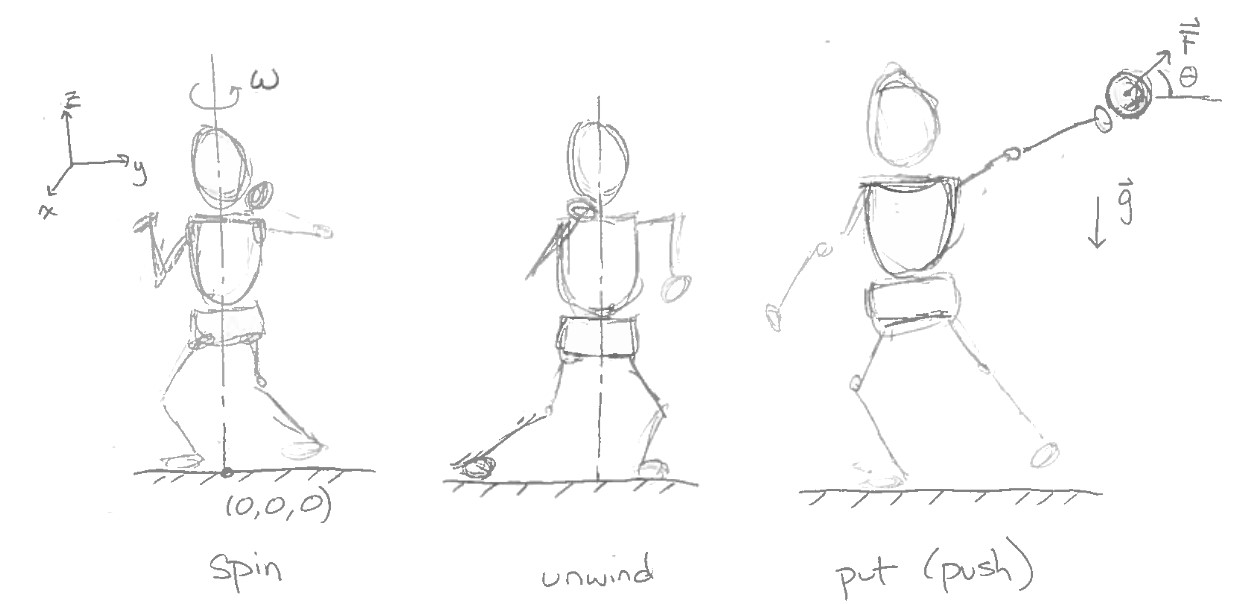

To implement that in Simulink, we used a series of solids and joints from [Simscape Multibody](https://www.mathworks.com/products/simscape-multibody.html). Here is what it looks like in the [Mechanics Explorer](https://www.mathworks.com/help/releases/R2024a/sm/ref/mechanicsexplorer-app.html):

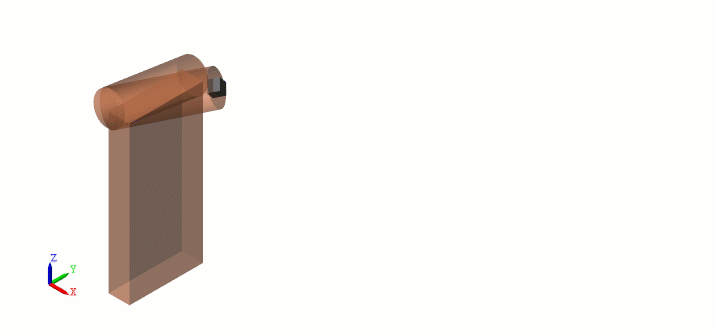

Let's see how I started with the [2016 model](https://blogs.mathworks.com/images/simulink/2016Q3/throwerDemo.slx) and improved it using new features available in MATLAB R2024a.

## Upgrade Advisor

The first thing I did when opening the model from R2016 is to run the [Upgrade Advisor](https://www.mathworks.com/help/releases/R2024a/simulink/slref/upgradeadvisor.html). The Upgrade Advisor is a useful tool that can identify potential enhancements to a model to take advantage of new features. In this case, it flagged 3 items:

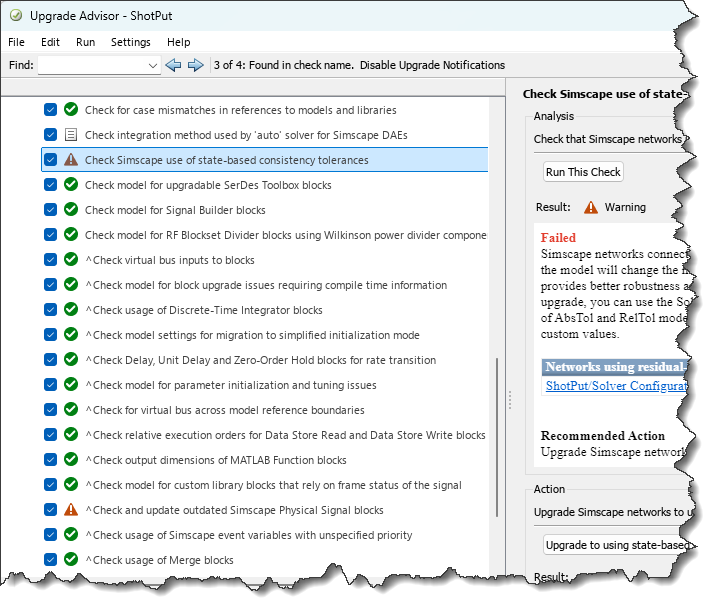

The Upgrade Advisor was able to automatically apply the following changes:

- Configure the model to use the solver "daessc" for Simscape models with differential algebraic equations. This new solver is more robust to solve the type of equations produced by Simscape.

- Change the [Solver Configuration](https://www.mathworks.com/help/releases/R2024a/simscape/ref/solverconfiguration.html) block to use state-based absolute and relative consistency tolerances during initialization. Introduced in R2022b, this provides better robustness and efficiency during the initialization, especially when using [Simscape nominal values](https://www.mathworks.com/help/releases/R2024a/simscape/ug/system-scaling-by-nominal-values.html).

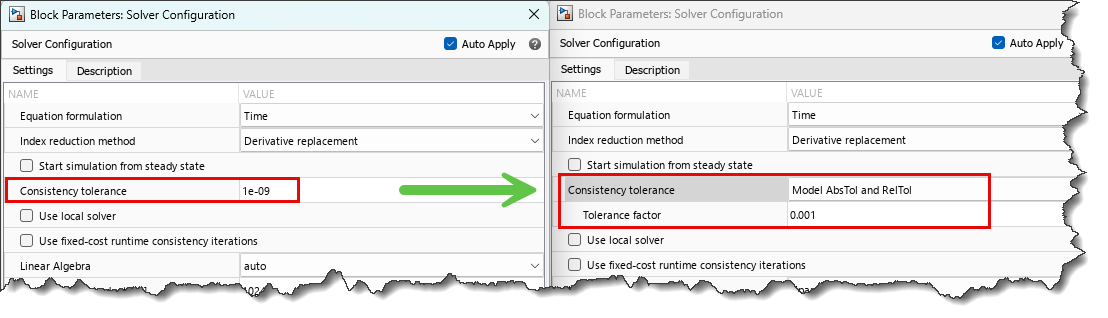

- Update Simscape physical signal blocks to propagate units, which was not possible in 2016. In my case, for example, it set the unit of the PS Constant block to "rad/s" because that's what the Revolute Joint downstream expects.

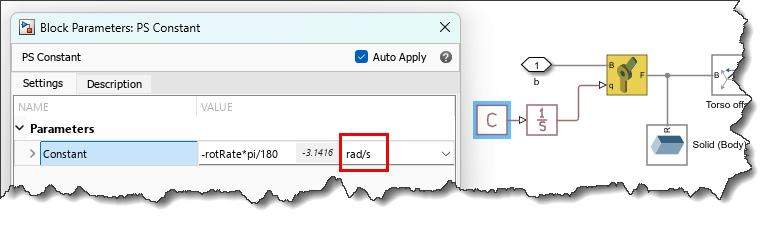

After just a few clicks, the model was ready to use in MATLAB R2024a.

## Locking Joints

In 2016, in order to keep the shot in the hand of the athlete, we had to implement a custom force rule that would be disabled at the time of releasing the shot. This was not ideal because this force rule was computationally expensive and making the simulation slow.

So the first improvement I did to the model is leveraging the "mode" property of Simscape Multibody joints. This feature, introduced a few releases ago, allows any joint to be locked or unlocked based on an input signal.

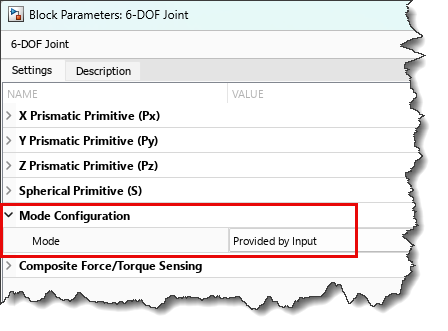

This adds an input port to the Join block that I can control from my Stateflow chart.

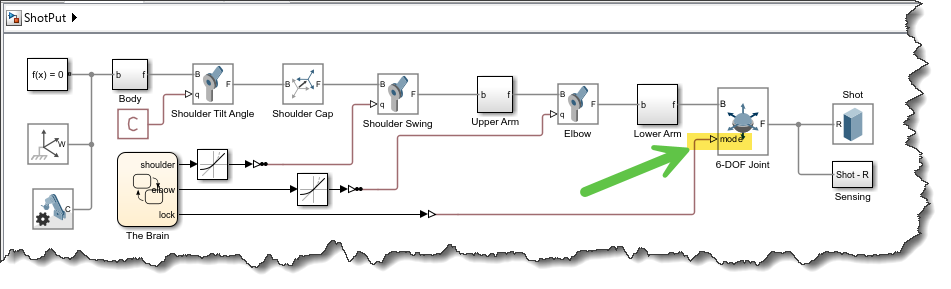

## Solid Block Frames

Another feature added to [Simscape Multibody](https://www.mathworks.com/products/simscape-multibody.html) that I like is the possibility to add additional frames to the [Solid](https://www.mathworks.com/help/releases/R2024a/sm/ref/bricksolid.html) blocks. For each section of the arm, I defined frames at both ends of the limb.

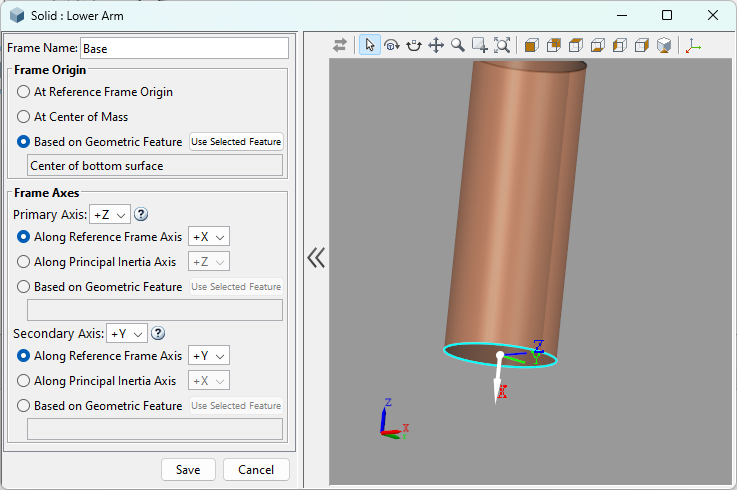

That way, I can get rid of the [Rigid Transform](https://www.mathworks.com/help/releases/R2024a/sm/ref/rigidtransform.html) blocks that had to be used before. There is nothing fundamentally wrong with using Rigid Transform, but I find adding frames to the Body block makes the model easier to understand at first look.

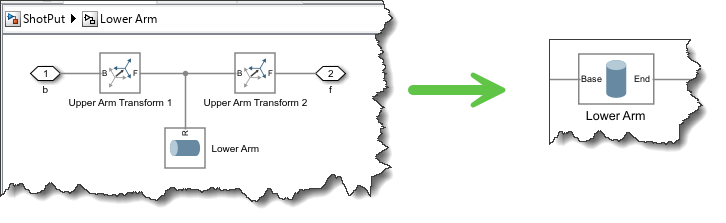

With those changes, here is what the model looks like:

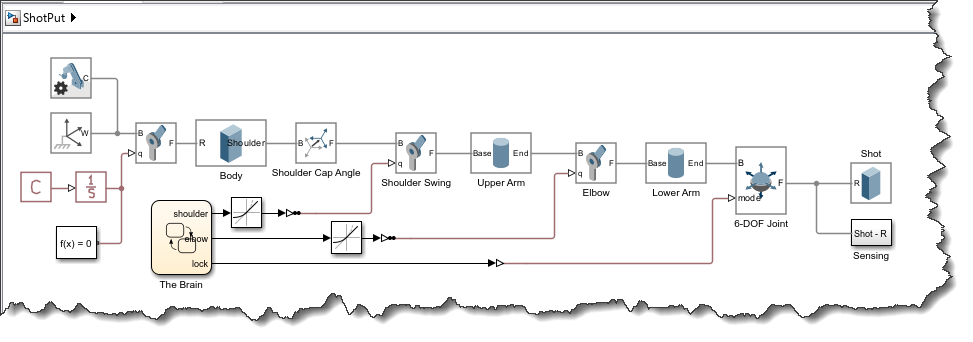

## Logging Simscape Variables as Simulink Signals

The last change I made to the model is in the Sensing subsystem. In 2016, we had to use Transform Sensor blocks and PS-Simulink blocks to get the information we needed out of Simscape Multibody. In R2024a, we added the possibility to [directly log Simscape variables as if they were Simulink signals](https://www.mathworks.com/help/releases/R2024a/simscape/ug/log-data-for-selected-blocks-only.html).

When selecting a Simscape block, go to the Simscape Block tab in the toolstrip and enable **Log Variables**. In the Model Data Editor, you will see a Simscape Variables tab appear  where you can select which variables to log and give them the name you desire.

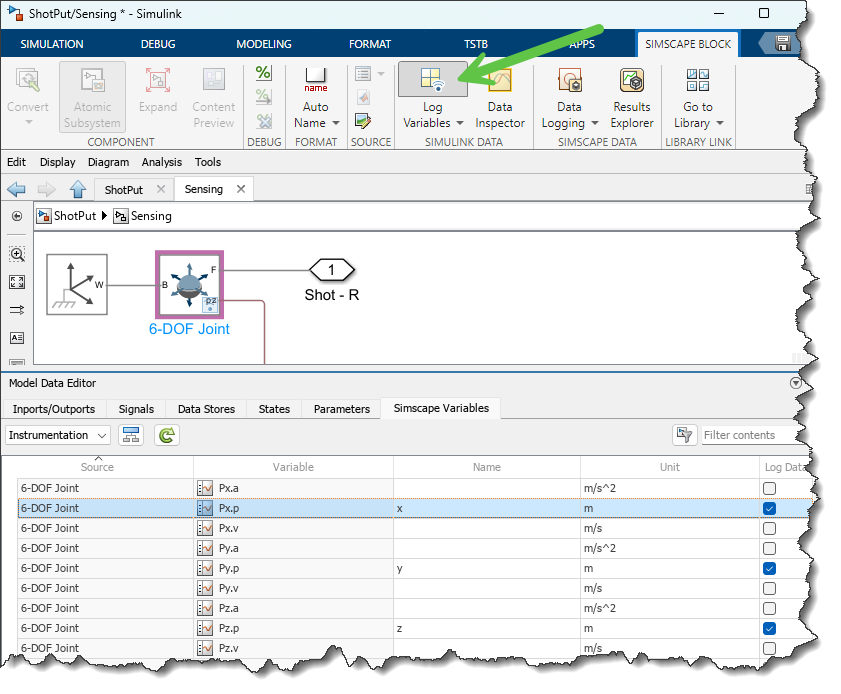

When simulating the model, they will show up in the "logsout".

mdl = "ShotPut";
out = sim(mdl);
out.logsout

ans = Simulink.SimulationData.Dataset 'logsout' with 3 elements

                           Name  BlockPath                   
                           ____  ___________________________ 
    1  [1x1 Variable]      x     ShotPut/Sensing/6-DOF Joint
    2  [1x1 Variable]      y     ShotPut/Sensing/6-DOF Joint
    3  [1x1 Variable]      z     ShotPut/Sensing/6-DOF Joint

  - Use braces { } to access, modify, or add elements using index.


## Design Study

With those changes done, I decided to study the impact of some parameters on the simulation results. For that, I can use the new [Design Study](https://www.mathworks.com/help/releases/R2024a/simulink/slref/designstudy.html) introduced in R2024a.

First, I specified a variable `shoulderAngle` in the Rigid Transform block controlling the shoulder angle and marked it as [Run-Time tunable](https://www.mathworks.com/help/releases/R2024a/simscape/run-time-parameters.html), so I can tune it when the model is simulated in Fast Restart mode.

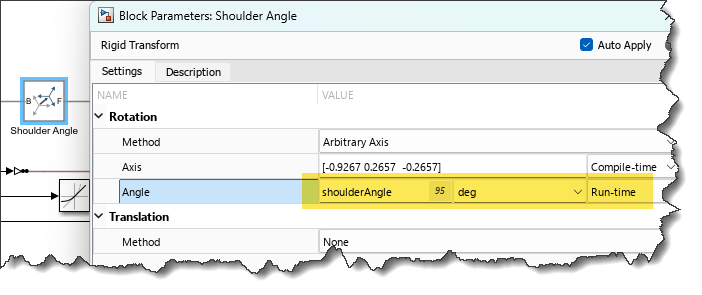

I created a design study with an array of 10 values from 45 degrees to 135 degrees.

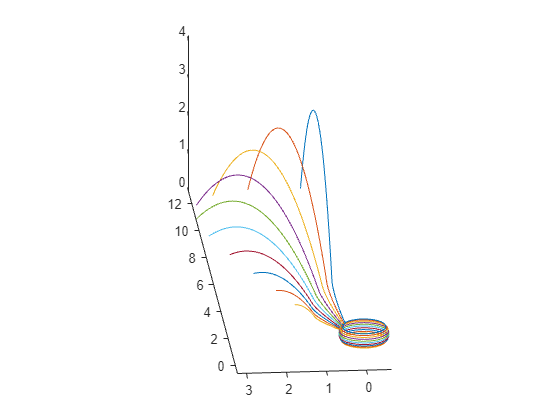

ShoulderAngleVar = simulink.multisim.Variable("shoulderAngle", linspace(45,135,10));
d = simulink.multisim.DesignStudy(mdl,ShoulderAngleVar);
out = parsim(d,'ShowProgress','off','UseFastRestart','on');
figure
hold on
for i = 1:length(out)
    plot3(out(i).logsout.get('x').Values.Data,...
        out(i).logsout.get('y').Values.Data,...
        out(i).logsout.get('z').Values.Data)
end
view([-95.14 19.80])
axis equal

## Now it's your turn

Don't miss the shot put events at the Paris Olympics:

- [Men's shot put schedule](https://olympics.com/en/paris-2024/schedule/athletics/men-s-shot-put?day=undefined)

- [Women's shot put schedule](https://olympics.com/en/paris-2024/schedule/athletics/women-s-shot-put?day=undefined)

Are you using the Upgrade Advisor when upgrading to new MATLAB releases? Are you taking advantage of the new features add to Simscape and Simulink? Have you tried the new Design Study? Let us know in the comments below.